# Calculate Wall Thickness Given Factor of Safety

**Author:** Evan Olsen

**Date:** 01/25/2024

**Description: **Determines the necessary wall thickness to match a given factor of safety.

clc; clear; close all;

% Import Pre-calculated Variables in ANSYS. This will be a pain to do but
% the easiest method is to output pressure from your CFD simulation, and
% export wall temperature in terms of XYZ from your Transient Thermal
% simulation on the interior reference surface. Determine which data varies
% along your contour, typically the z-axis, and then import into matlab
% using the importtable() and table2array() functions. For reusability, you
% can save() to a .mat file.
load('ANSYS_P_x.mat')
load('ANSYS_T_x.mat')

% Pre-calculated from parametric-liquid-engine script located at 
% https://github.com/RIT-Launch-Initiative/parametric-liquid-engine or
% other script.
load('R_x.mat')

% Reversing ANSYS output variables to match the pre-calculated contour
% orientation. Edit this as needed, it changes depending on how your ANSYS
% geometry is set up.
ANSYS_T_x(:,1)=-ANSYS_T_x(:,1);
P_x(:,1)=-P_x(:,1);

% Neccessary Factor of Safety
FOS = 5.0;

## **Determining Allowable Stress Table for 304N Stainless Steel**

*Table 1. Allowable Stress Chart for 304N Stainless Steel*

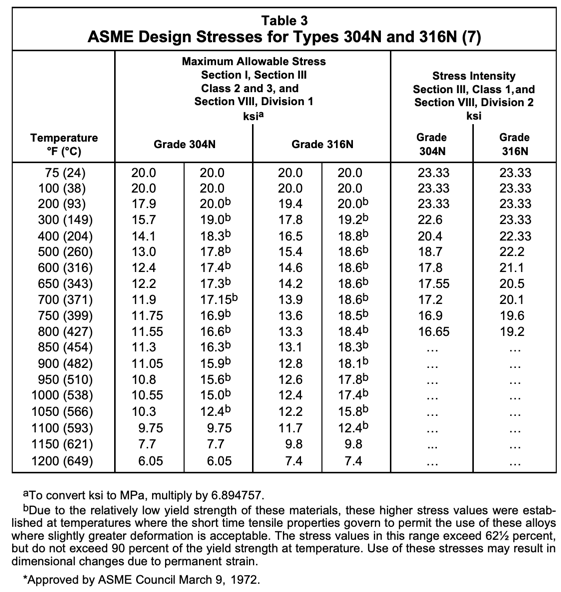

Source: [*http://www.cientificosaficionados.com/libros/cohetes.pdf*](http://www.cientificosaficionados.com/libros/cohetes.pdf)

% For 304N Stainless Steel - Allowable Stress Table
allowable_stress_tbl = [20, 20, 17.9, 15.7, 14.1, 13.0, 12.4, 12.2, 11.9, 11.75, 11.55, 11.3, 11.05, 10.8, 10.55, 10.3, 9.75, 7.7, 6.05];
temp_tbl = [24,38,93,149,204,260,316,343,371,399,427,454,482,510,538,566,593,621,649];

## **Creating Fit Curves to Equalize the Matrix Lengths**

This section uses the cftool() curve fitting tool within MATLAB to create curve fits for the allowable stress table, as well as using that function to equalize the matrix lengths. A linear curve fit is good enough for these purposes.

[fitresult_stress,~] = createFit_stress(temp_tbl,allowable_stress_tbl);

% Wall temperature on the exterior surface, for short burn times this will
% commonly be the ambient temperature.
T_out = 300; % [K]
% Evaluates the allowable stress at the outer surface.
allowable_stress_out = feval(fitresult_stress,T_out-273.15)*6.895e6; % [Pa]

% Evaluates the curve fit to detemrine the allowable stress on the interior
% wall in terms of the engine length. Converts the allowable stress
% determined from the feval() function from [ksi] to [Pa].
for i=1:length(ANSYS_T_x(:,2))
    allowable_stress_in(i) = feval(fitresult_stress,ANSYS_T_x(i,2)-273.15)*6.895e6; % [Pa]
end

% Calculates the average allowable stress between the outside and inside
% surfaces of the engine, to compensate for the fact that there is a
% temperature gradient from the inside surface to the outside. This method
% gives the most conservative answer compared to averaging the inner and
% outer wall temperatures, due to the increased change in allowable stress
% per unit temperature.
allowable_stress_avg = (allowable_stress_in + allowable_stress_out)./2; % [Pa]

% Creates a linear curve fit for the input pressure curve in order to
% equalize the lengths of the matrices with the inputted x-data within the
% wall temperature matrix.
[fitresult_pressure,~] = createFit_Pressure(P_x(:,1),P_x(:,2));
for j=1:length(ANSYS_T_x(:,1))
    internal_pressure(j) = feval(fitresult_pressure,ANSYS_T_x(j,1)); % [Pa]
end

% Creates a linear curve fit for the wall y-data to match the x-data in the
% wall temperature matrix.
[fitresult_wall,~] = createFit_wall(R_x(1,:),R_x(2,:));
for k=1:length(ANSYS_T_x(:,1))
    local_radius(k) = feval(fitresult_wall,ANSYS_T_x(k,1)); % [m]
end

## **Calculating Minimum Wall Thickness in Terms of X**

The following equation was given to determine the wall thickness for a certain allowable stress (S) on the wall. To incorporate our factor of safety, the allowable stress is divided by the FOS. This is equivalent to multiplying the wall thickness by the FOS. 

*Figure 1. Wall Thickness Equation for FOS 1.0*

Source: [*http://www.cientificosaficionados.com/libros/cohetes.pdf*](http://www.cientificosaficionados.com/libros/cohetes.pdf)

% We will define a base thickness for the contour to provide simple
% structure. This is important towards the end of the nozzle due to the
% required wall thickness being << than the required thickness in the
% combustion chamber.
base_thickness = 1e-3; % [m]

% Utilizes above defined equation in Figure 1. to determine the minimum
% wall thickness to meet the given factor of safety.
min_t_wall = (internal_pressure .* local_radius .* FOS)./allowable_stress_avg; % [m]

% To determine the external wall radius (outside contour), you add the
% minimum additional wall thickness and the base thickness to the local
% interior radius.
external_radius = local_radius + min_t_wall + base_thickness; % [m]

local_radius_flipped = fliplr(local_radius);
external_radius_flipped = fliplr(external_radius);

xdata = flipud(ANSYS_T_x(:,1))'

xdata =    -0.1057   -0.1042   -0.1042   -0.1028   -0.1027   -0.1013   -0.1013   -0.0998   -0.0983   -0.0969   -0.0968   -0.0954   -0.0939   -0.0924   -0.0910   -0.0909   -0.0895   -0.0894   -0.0880   -0.0865   -0.0851   -0.0850   -0.0836   -0.0835   -0.0821   -0.0806   -0.0792   -0.0791   -0.0777   -0.0776   -0.0762   -0.0761   -0.0747   -0.0733   -0.0732   -0.0718   -0.0717   -0.0703   -0.0702   -0.0688   -0.0674   -0.0673   -0.0659   -0.0658   -0.0644   -0.0643   -0.0629   -0.0628   -0.0615   -0.0614


zdata = zeros(1,length(xdata));

internalContour = [xdata;local_radius_flipped;zdata]

internalContour =    -0.1057   -0.1042   -0.1042   -0.1028   -0.1027   -0.1013   -0.1013   -0.0998   -0.0983   -0.0969   -0.0968   -0.0954   -0.0939   -0.0924   -0.0910   -0.0909   -0.0895   -0.0894   -0.0880   -0.0865   -0.0851   -0.0850   -0.0836   -0.0835   -0.0821   -0.0806   -0.0792   -0.0791   -0.0777   -0.0776   -0.0762   -0.0761   -0.0747   -0.0733   -0.0732   -0.0718   -0.0717   -0.0703   -0.0702   -0.0688   -0.0674   -0.0673   -0.0659   -0.0658   -0.0644   -0.0643   -0.0629   -0.0628   -0.0615   -0.0614
    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254 

externalContour = [xdata;external_radius_flipped;zdata];

csvwrite('internalContour.csv',internalContour);
csvwrite('externalContour.csv',externalContour);

## **Plotting**

This section plots the data to graphically show the change in allowable stress over the length of the engine, and which regions are more "fragile" and require additional thickness. From the results you can deduce that the pressure acting on the walls is the majority driving factor for the wall thickness, assuming reasonable wall temperatures. Of course, if the wall temperatures reach past the curve fit for the allowable stress, wall temperature will be a major factor in wall thickness.

wallThicknessPlot = figure('Name','Wall Thickness for Given FOS');

% Plot 1 of 3
subplot(3,1,1)
hold on
% Inner Surface Allowable Stress
plot(ANSYS_T_x(:,1),allowable_stress_in/1e6,'-b');
% Outer Surface Allowable Stress (Straight Line, typically)
plot([ANSYS_T_x(1,1), ANSYS_T_x(end,1)],[allowable_stress_out/1e6,allowable_stress_out/1e6],'-r');
% Average Allowable Stress Between Inner and Outer Surfaces
plot(ANSYS_T_x(:,1),allowable_stress_avg/1e6,'-g');
ylim([0 inf]);
grid on; grid minor;
title('Allowable Stress vs. Length'); xlabel('L_e, x [m]'); ylabel('\sigma_a [MPa]');
lgd_allowableStressPlot = legend('Inside Wall \sigma_a','Outside Wall \sigma_a','Average \sigma_a');
lgd_allowableStressPlot.Location = "southwest";

% Plot 2 of 3
subplot(3,1,2)
% Pressure on Internal Surface
plot(ANSYS_T_x(:,1),internal_pressure,'-b')
ylim([0 inf]);
grid on; grid minor;
title('Internal Pressure vs. Length'); xlabel('L_e, x [m]'); ylabel('P_i [Pa]');

% Plot 3 of 3
subplot(3,1,3)
hold on
% External Radius
plot(ANSYS_T_x(:,1),external_radius,'k')
% Internal Radius
plot(ANSYS_T_x(:,1),local_radius,'k')
title_str = sprintf('%.1f',FOS) +" - FOS Wall Thickness"; 
title(title_str);
xlabel('L_e, x [m]'); ylabel('R [m]');
ylim([0 inf]);
grid on; grid minor; axis equal;

allowableStressPlot = figure('Name','Allowable Stress Curves');

% Plot 1 of 3
subplot(3,1,1)
% Allowable Stress Curve Fit w/ Datapoints
plot(fitresult_stress,'k',temp_tbl,allowable_stress_tbl,'-o')
xlim([0 700]);ylim([0 inf])
title('Allowable Stress Curve Fit');xlabel('T_w [K]'); ylabel('\sigma_a [ksi]');
grid on;grid minor;
lgd_allowableStressFitPlot = legend('Raw Data','Curve Fit');
lgd_allowableStressFitPlot.Location = "southwest";

% Plot 2 of 3
subplot(3,1,2)
hold on
% Interior Wall Temperature
plot(ANSYS_T_x(:,1),ANSYS_T_x(:,2),'-r')
% Exterior Wall Temperature
plot([ANSYS_T_x(1,1),ANSYS_T_x(end,1)],[T_out,T_out],'-b')
ylim([0 inf]);
title('Interior Wall Temperature vs. Length');xlabel('L_e, x [m]');ylabel('T_\sigma [K]');
grid on;grid minor;
legend('T_i','T_o')

% Plot 3 of 3
subplot(3,1,3)
hold on
% Inner Surface Allowable Stress
plot(ANSYS_T_x(:,1),allowable_stress_in/1e6,'-b');
% Outer Surface Allowable Stress (Straight Line, typically)
plot([ANSYS_T_x(1,1), ANSYS_T_x(end,1)],[allowable_stress_out/1e6,allowable_stress_out/1e6],'-r');
% Average Allowable Stress Between Inner and Outer Surfaces
plot(ANSYS_T_x(:,1),allowable_stress_avg/1e6,'-g');
ylim([0 inf]);
grid on; grid minor;
title('Allowable Stress vs. Length'); xlabel('L_e, x [m]'); ylabel('\sigma_a [MPa]');
lgd_allowableStressPlot = legend('Inside Wall \sigma_a','Outside Wall \sigma_a','Average \sigma_a');
lgd_allowableStressPlot.Location = "southwest";

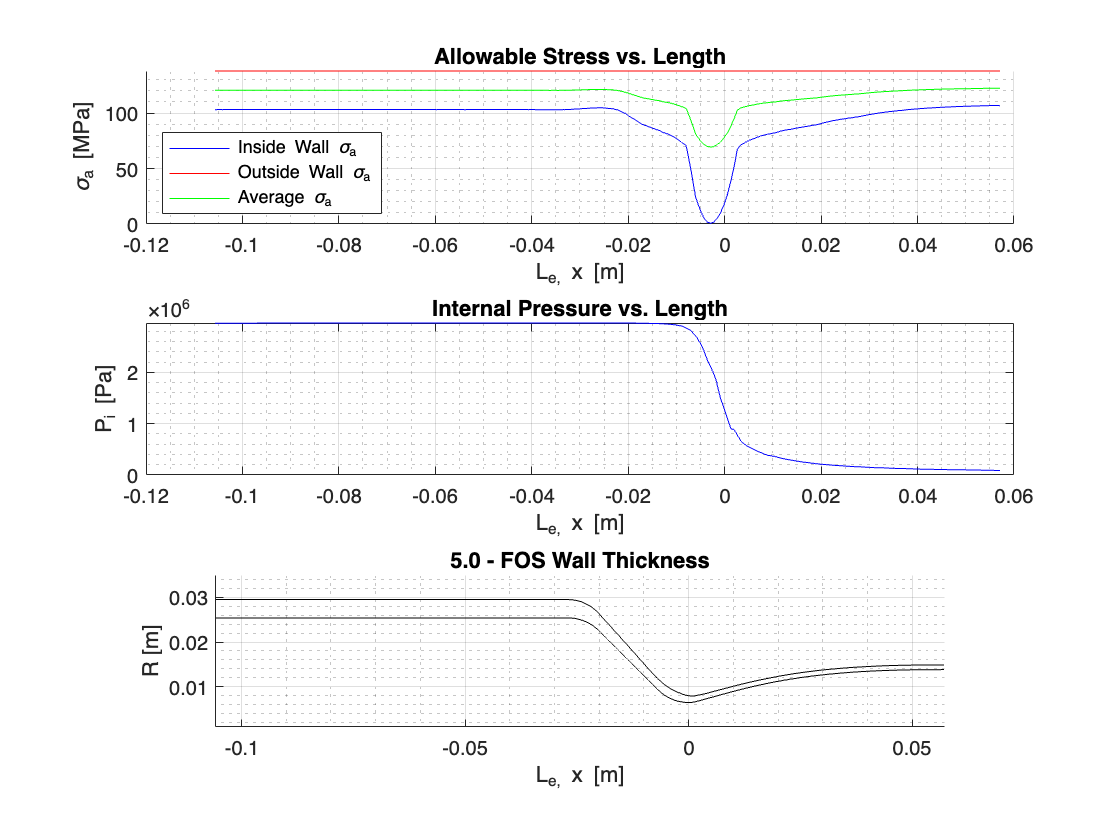

% Save Plot 1 as a PNG file
saveas(wallThicknessPlot,'wallThicknessPlot','png')

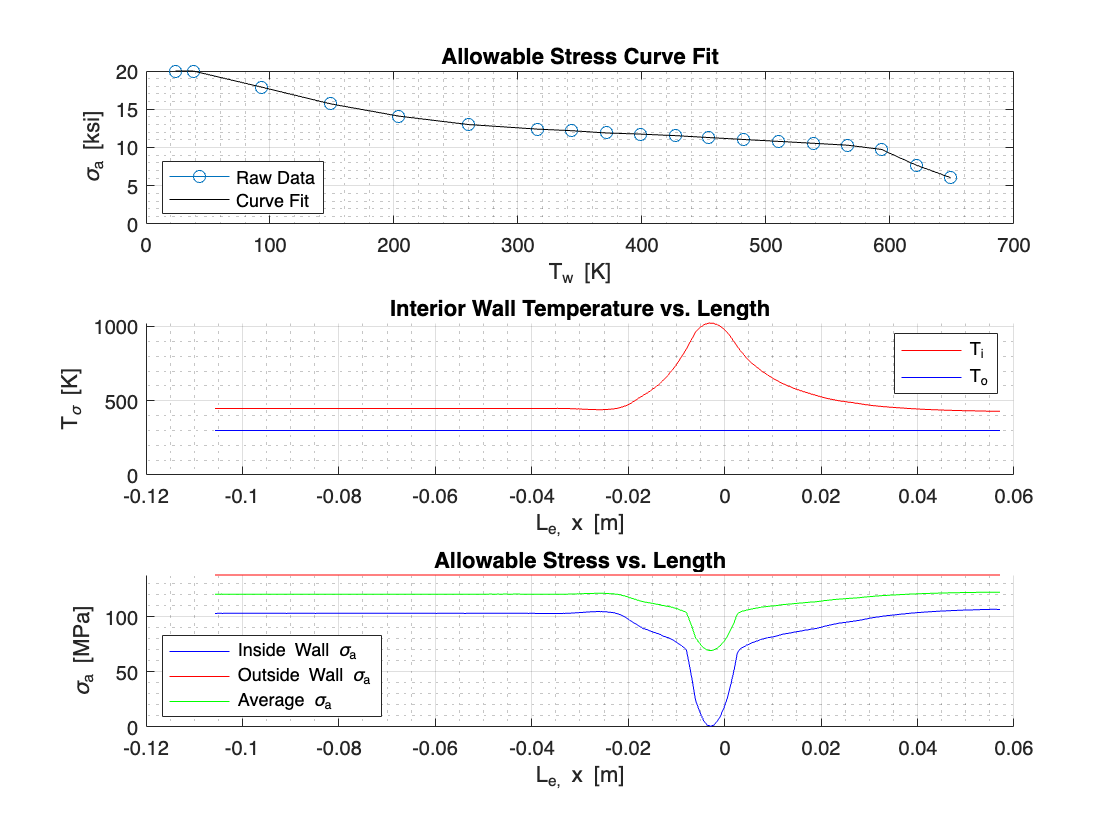

% Save Plot 2 as a PNG file
saveas(allowableStressPlot,'allowableStressPlot','png')